# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.14 这两幅图怎么用LaTex或者Matlab实现?

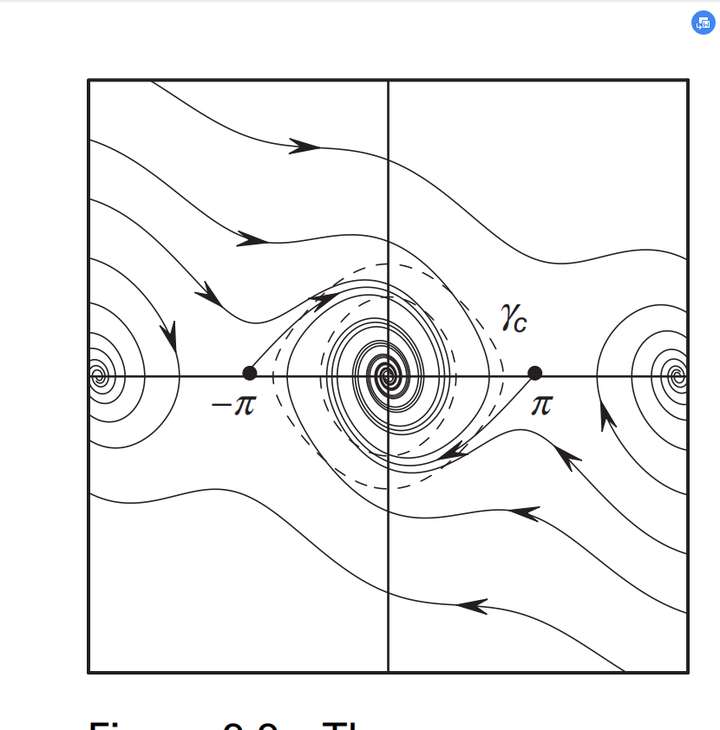

原问题：[https://www.zhihu.com/question/631503383/answer/3299999294](https://www.zhihu.com/question/631503383/answer/3299999294)

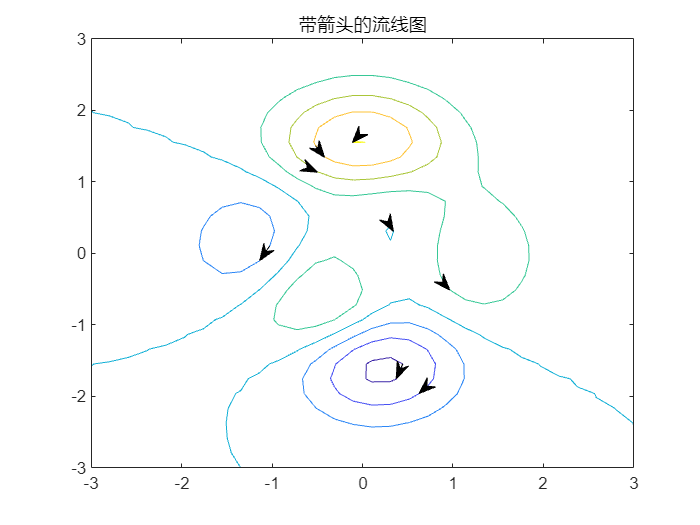

clear;clc;close all;
[x, y, z] = peaks(30);
[M, c] = contour(x, y, z);
% 每条轮廓的数据
level = c.LevelList;
len = length(level);
xs = cell(len, 1);
ys = cell(len, 1);
for i = 1:len - 1
    index1 = find(M(1, :) == level(i));
    index2 = find(M(1, :) == level(i + 1));
    xs{i} = M(1, index1+1 : index2-1);
    ys{i} = M(2, index1+1 : index2-1);
end
xs{len} = M(1, index2+1 : end);
ys{len} = M(2, index2+1 : end);

% 下面开始画箭头，涉及到坐标的转换
% 获取 Axes 位置
posAxes = get(gca, 'Position');
posX = posAxes(1);
posY = posAxes(2);
width = posAxes(3);
height = posAxes(4);
% 获取 Axes 范围
limX = get(gca, 'Xlim');
limY = get(gca, 'Ylim');
minX = limX(1);
maxX = limX(2);
minY = limY(1);
maxY = limY(2);
% 遍历，逐条流线加箭头
for i = 1 : len
    % 获取每条流线的数据
    xData = xs{i};
    yData = ys{i};
    % 这里取的是最后两个点，一定要是相邻的两个点用来确定箭头方向
    x0 = xData(end-1 : end);
    y0 = yData(end-1 : end);
    % 转换坐标到相对于figure的坐标
    xNew = posX + (x0 - minX) / (maxX - minX) * width;
    yNew = posY + (y0 - minY) / (maxY - minY) * height;
    % 画箭头
    hold on
    annotation('arrow', xNew, yNew);
end
hold off
title('带箭头的流线图');